Specify path to training data and testing data

imdsTrain = imageDatastore('C:\Users\user\Documents\data\X-ray Data Sets Full\train',...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

imdsTest = imageDatastore('C:\Users\user\Documents\data\X-ray Data Sets Full\valid',...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

Specify CNN architecture to be used

net = googlenet;

Layer to be remove, preparing for fine-tuning

lgraph = layerGraph(net);
inputSize = net.Layers(1).InputSize(1:2);
lgraph = removeLayers(lgraph, {'loss3-classifier','prob','output'});

Add new fc layers

numClasses = numel(categories(imdsTrain.Labels));
newLayers = [
    fullyConnectedLayer(numClasses,'Name','fc',...
    'WeightLearnRateFactor',10,'BiasLearnRateFactor',10)
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classoutput')];
lgraph = addLayers(lgraph,newLayers);

lgraph = connectLayers(lgraph,'pool5-drop_7x7_s1','fc');

Freeze weight on first few layers

layers = lgraph.Layers;
connections = lgraph.Connections;

% freezeWeights(layers(1:110));
for i = 1:110
        if isprop(layers(i),'WeightLearnRateFactor')
            layers(i).WeightLearnRateFactor = 0;
        end
        if isprop(layers(i),'WeightL2Factor')
            layers(i).WeightL2Factor = 0;
        end
        if isprop(layers(i),'BiasLearnRateFactor')
            layers(i).BiasLearnRateFactor = 0;
        end
        if isprop(layers(i),'BiasL2Factor')
            layers(i).BiasL2Factor = 0;
        end
end

%lgraph = createLgraphUsingConnections(layers,connections);

lgraph = layerGraph();
for i = 1:numel(layers)
    lgraph = addLayers(lgraph,layers(i));
end

for c = 1:size(connections,1)
    lgraph = connectLayers(lgraph,connections.Source{c},connections.Destination{c});
end

Data augmnetation

pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, 'ColorPreprocessing', 'gray2rgb',...
    'DataAugmentation',imageAugmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation, 'ColorPreprocessing', 'gray2rgb');

Training option

options = trainingOptions('sgdm', ...
    'MiniBatchSize',32, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',0.0001, ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'ValidationPatience',Inf, ...
    'Verbose',0 ,...
    'ExecutionEnvironment', 'gpu',...
    'Plots','training-progress');

Start training with google net

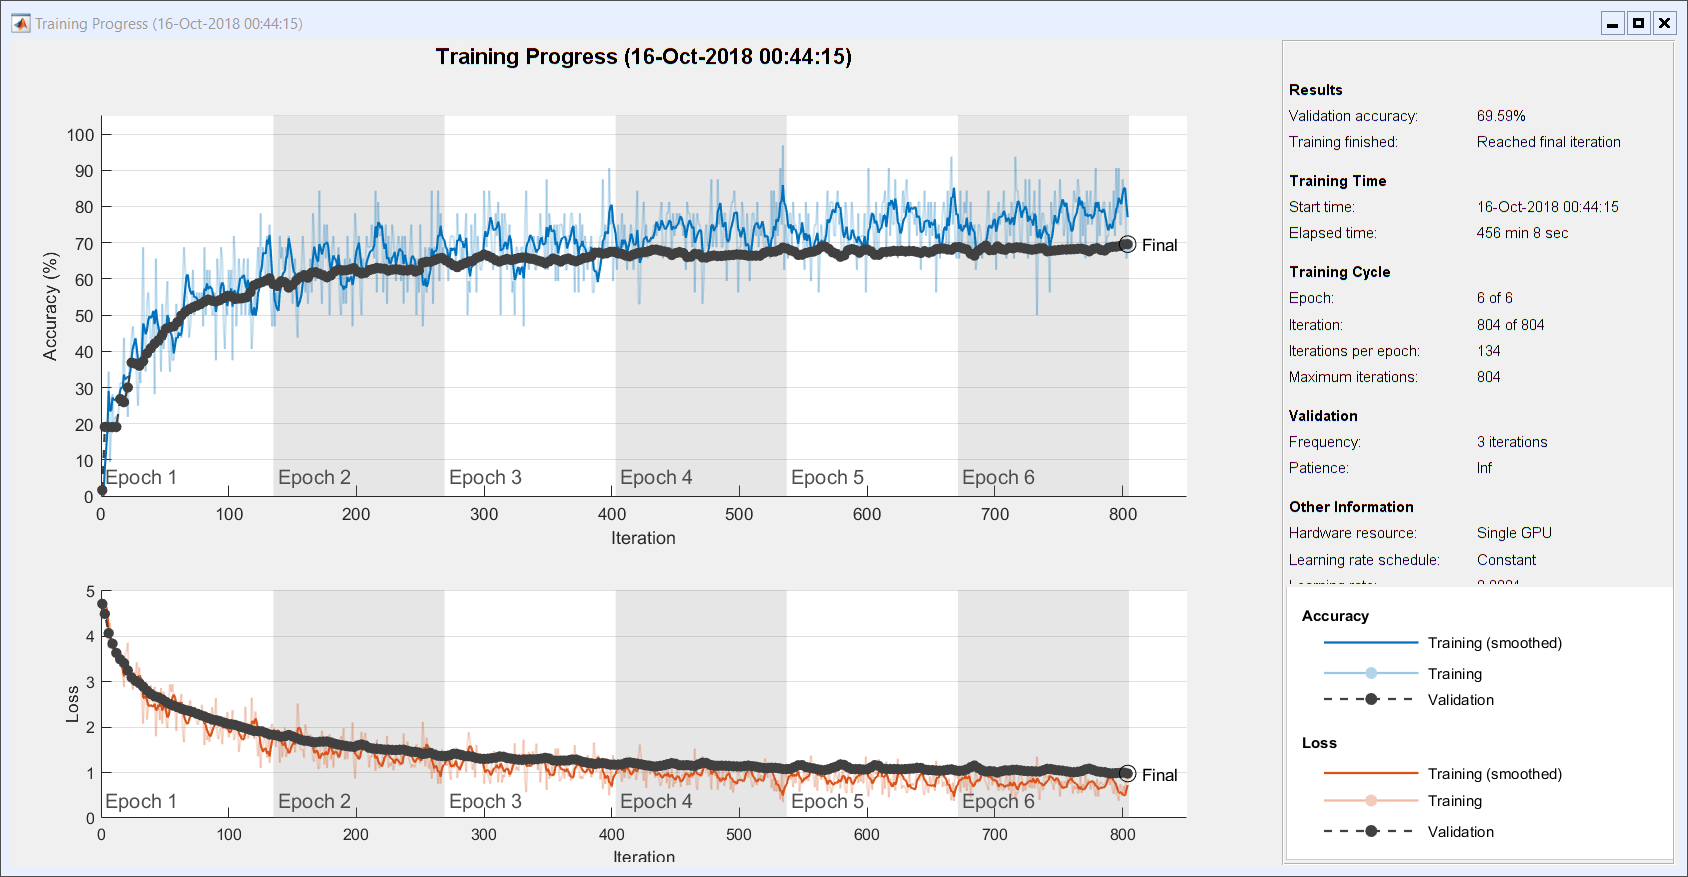

net = trainNetwork(augimdsTrain,lgraph,options);

save googlenet_trained

Get accuracy

[YPred,probs] = classify(net,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels);

save probability_googlenet probs